# Taller H infinito recuperación

Felipe Forero, Andrés Holguín, Andrés Morales

Departamento de Ingeniería Mecánica y Mecatrónica

Universidad Nacional de Colombia

Bogotá, Colombia

## Controlador SAS/CAS

Sistema de aumento de estabilidad y control. 

### Modelo Longitudinal 

load("modelo_lin.mat", "longmod") % Cargamos el modelo 
size(longmod); 

State-space model with 7 outputs, 2 inputs, and 6 states.


strcat(longmod.InputName') % Nombres de las entradas del sistema

ans = 1×2 cell array
    {'elevator'}    {'throttle'}


strcat(longmod.OutputName') % Nombres de las salidas del sistema

ans = 1×7 cell array
    {'V'}    {'alpha'}    {'q'}    {'theta'}    {'h'}    {'ax'}    {'az'}


Nos limitamos al control del sistema por la acción del elevator. $U_1$. Como objetivo de diseño, nos enfocamos en el control del cabeceo del avión (theta), buscando un regulador de velocidad (q) 

MT_longmod = tf(longmod); % Matriz de tranferencia 
TF_elevator2theta = MT_longmod(4,1)

TF_elevator2theta =
 
  From input "elevator" to output "theta":
          -134.1 s^4 - 1869 s^3 - 6807 s^2 - 2268 s - 0.07966
  --------------------------------------------------------------------
  s^6 + 29.95 s^5 + 392.9 s^4 + 1609 s^3 + 637.7 s^2 + 642 s + 0.07726
 
Continuous-time transfer function.



TF_elevator2thetadot = MT_longmod(3, 1); 

Se realiza una revisión de respuesta el paso en lazo abierto. 

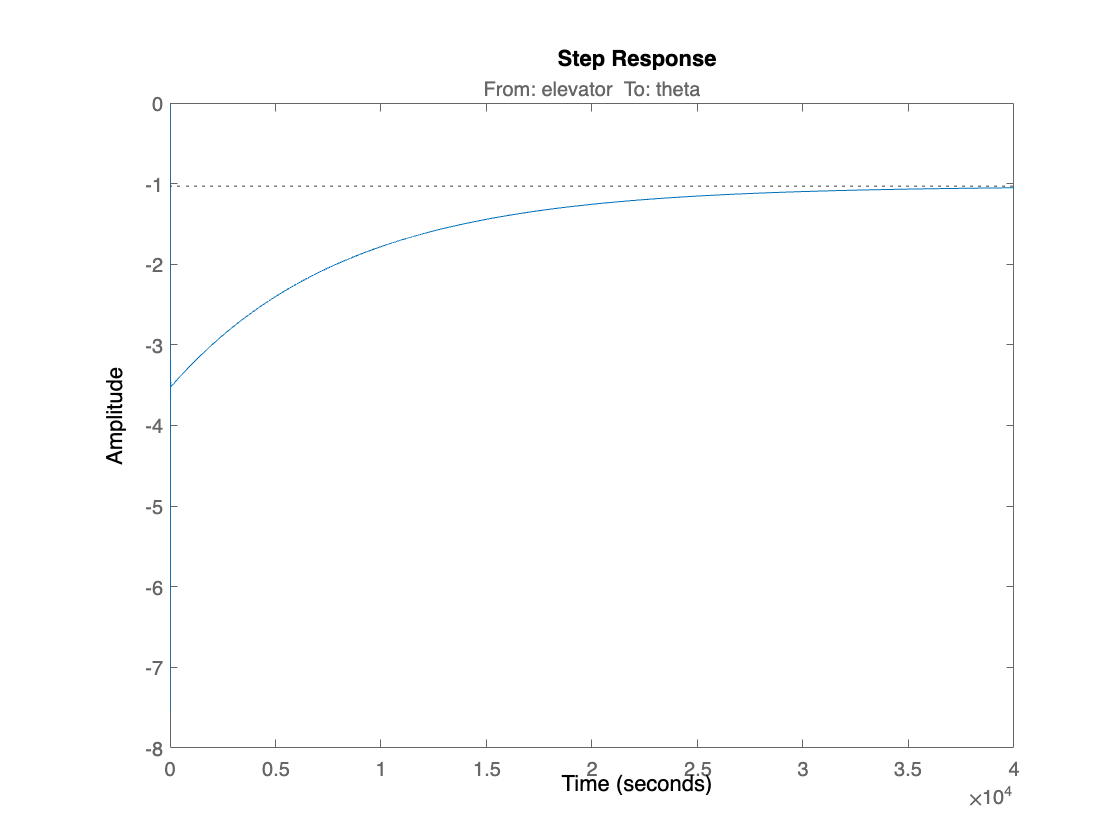

step(TF_elevator2theta); 

% Revision de características del sistema 
damp(TF_elevator2theta); 

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    


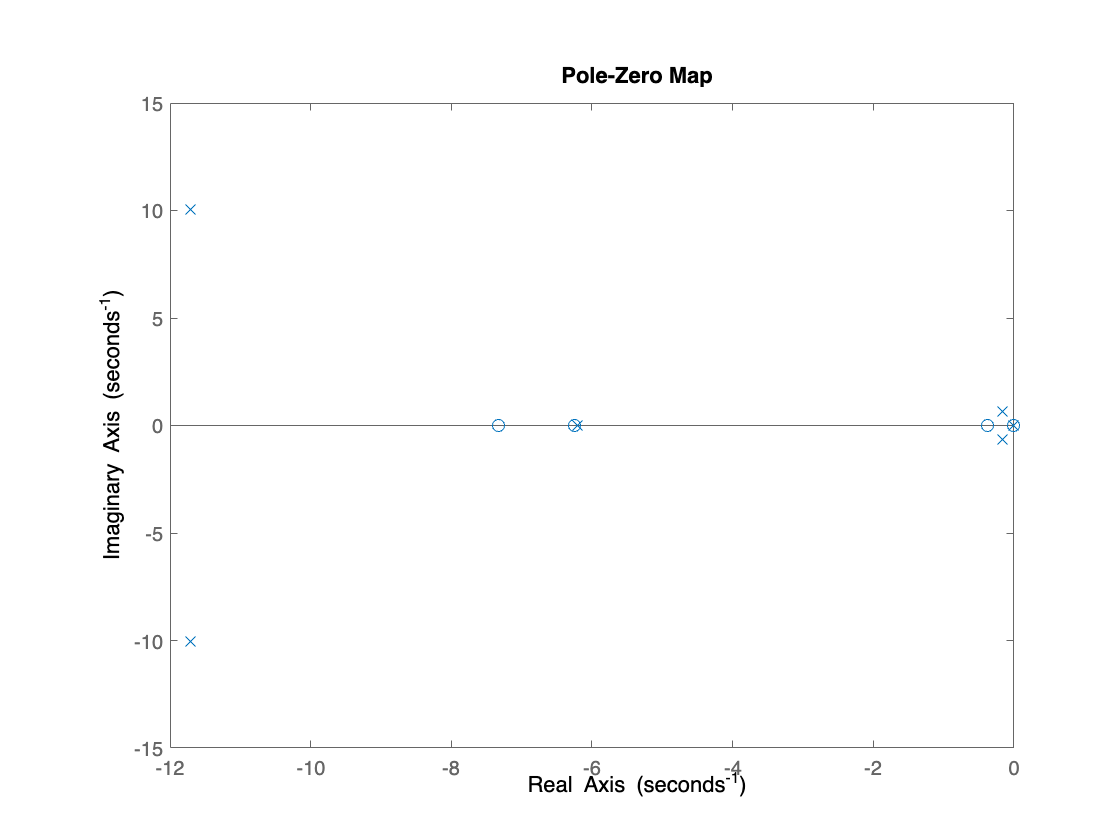

pzmap(TF_elevator2theta); 

## Diseño de CAS/SAS

Por el contexto del sistema, el avión requiere una respuesta rápida de control. Definimos una meta de máx 5 segundos de tiempo de establecimiento, y el menor sobrepico posible. 

Comenzamos con una retroalimentacion de velocidad para aumentar la estabilidad del sistema. 

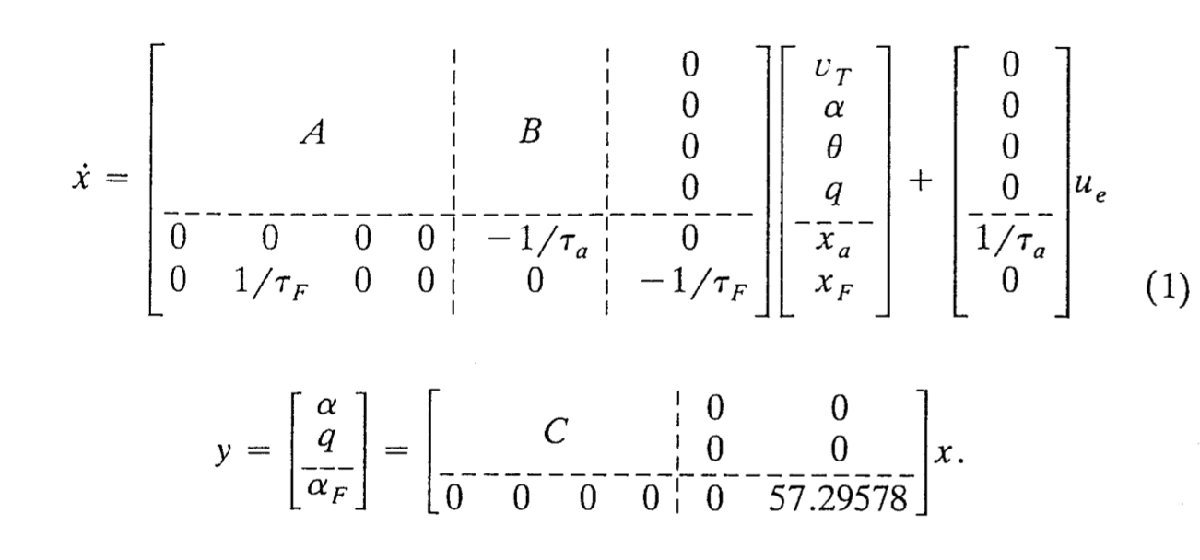

**Figura**: Ejemplo de diseño de SAS para modo de fugoide estable con feedback de aceleracion y pitch-rate

% Mirar los estados 
strcat(longmod.StateName')

ans = 1×6 cell array
    {'u'}    {'w'}    {'q'}    {'theta'}    {'Ze'}    {'omega'}


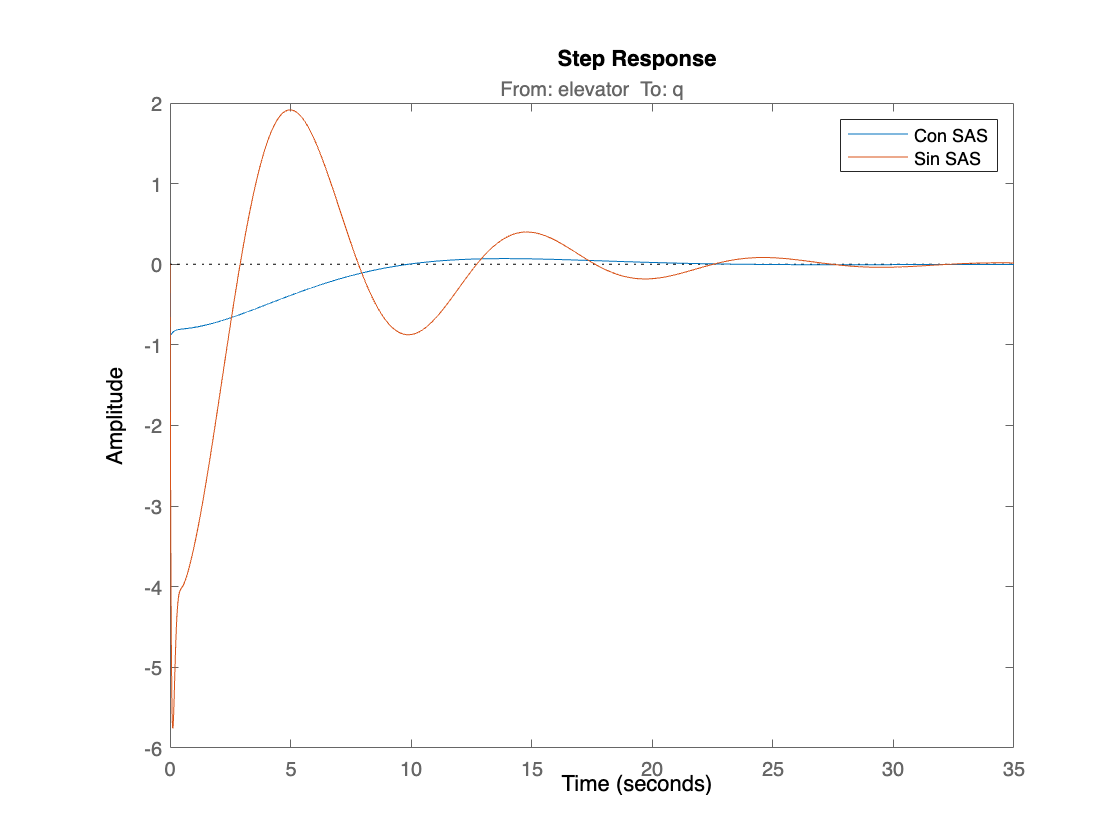

A = longmod.A; B = longmod.B; C = longmod.C; D = longmod.D; 
% Ganancias de retroalimentacion  dim 2xn 
K = [0 0 1 0 0 0; 
     0 0 0 0 0 0]; 

A_sas = [A + B * K,zeros(6, 1); C(2,:), 0]; 
B_sas = [B; zeros(1, 2)];
C_sas = [C, zeros(7, 1)];

longmod_sas = ss(A_sas, B_sas , C_sas, D); 
MT_longmod_sas = tf(longmod_sas);
TF_elevator2thetadot_sas = MT_longmod_sas(3, 1); 
step(TF_elevator2thetadot_sas, TF_elevator2thetadot);
legend("Con SAS", "Sin SAS")

Así se logra amortiguar el sistema, y mejorar la repuesta de regulación de velocidad. Se procede a agregar el CAS. 

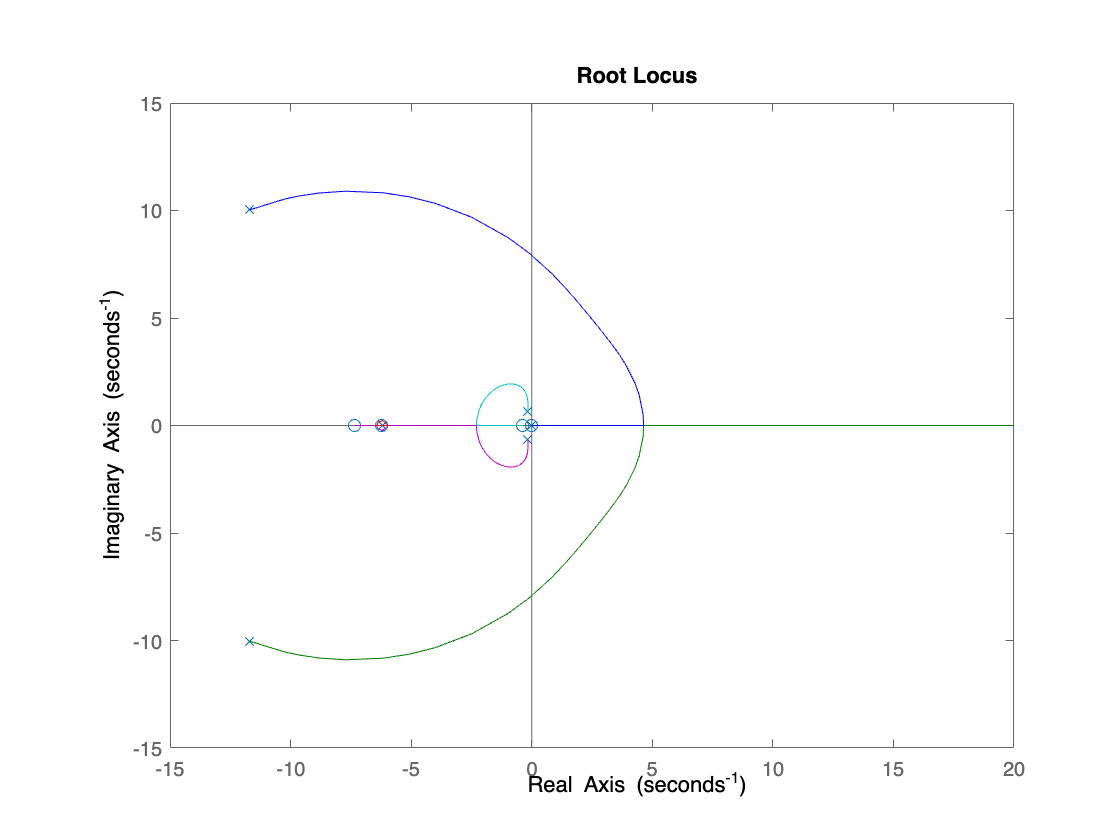

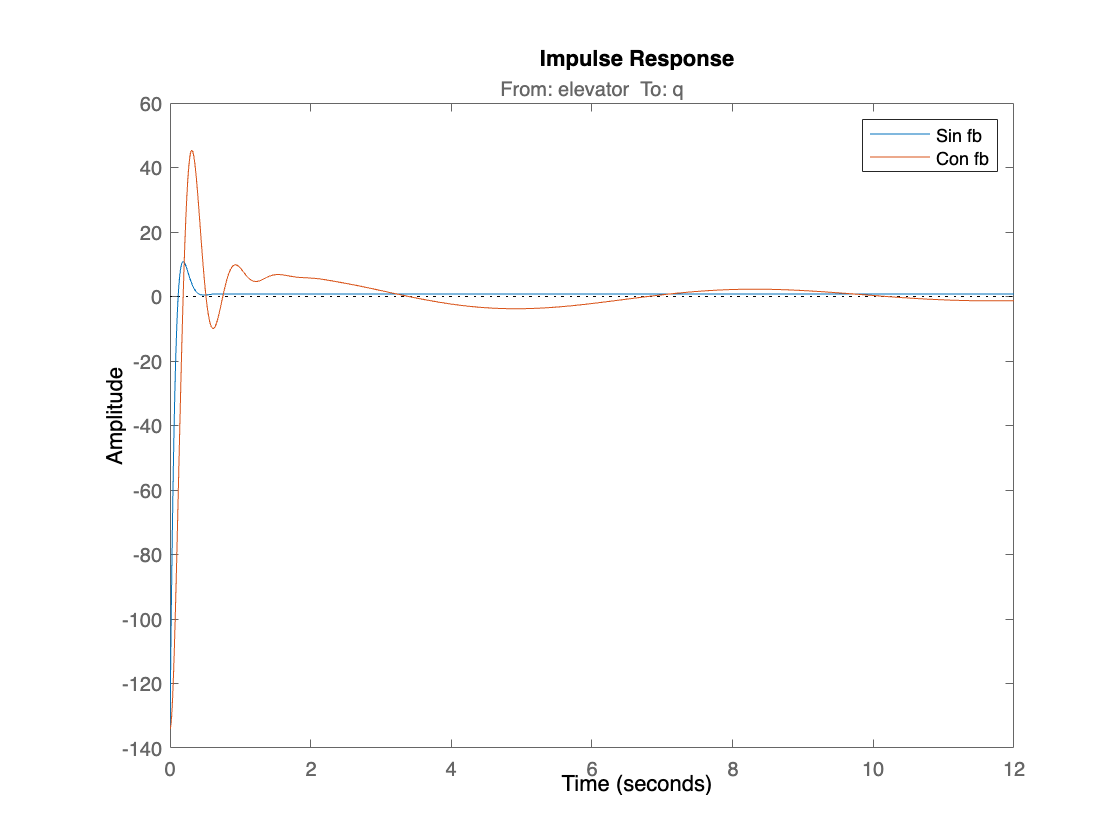

rlocus(TF_elevator2thetadot); 


### Modelo Lateral/Direccional

load("modelo_lin.mat")
latmod

latmod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r   

latmod.A(4,4) = 0;
latmod.A(5,4) = 0;

#### Funciones de transferencia

Se comienza por encontrar las funciones de transferencia del sistema a partir del modelo lateral/direccional suministrado.

TransferFunctions = tf(latmod)

TransferFunctions =
 
  From input "aileron" to output...
                 -19.49 s^2 - 214.7 s - 225.8
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
          -156.9 s^3 - 535 s^2 - 4302 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
                 -156.3 s^2 - 528.8 s - 4308
   phi:  -------------------------------------------
         s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
  From input "rudder" to output...
            0.3128 s^3 + 87.06 s^2 + 1309 s - 209.3
   beta:  -------------------------------------------
          s^4 + 19.8

#### SAS Controllers

Se comienza por establecer la función de transferencia para el roll rate a partir de la entrada del aileron, que permitirá determinar la ganancia derivativa del controlador.


$$G_1 =\;\frac{p}{\textrm{aileron}}$$


G1 = TransferFunctions(2,1)

G1 =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



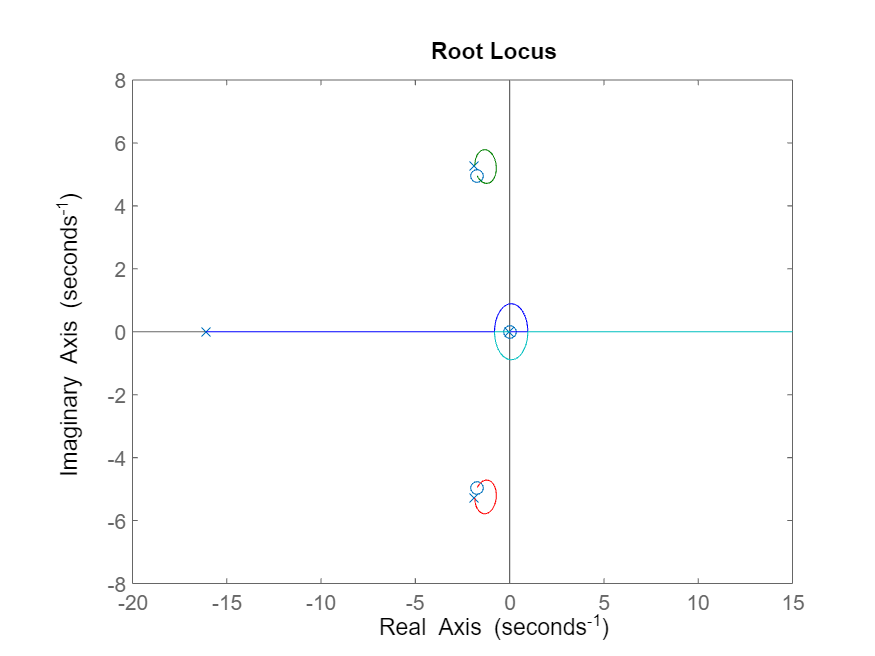

rlocus(G1)

kd1 = 0.106;
Go1 = feedback(kd1*G1,1);
Go1.OutputName= {'p'}

Go1 =
 
  From input "aileron" to output "p":
     -16.63 s^3 - 56.71 s^2 - 456 s + 13.14
  ---------------------------------------------
  s^4 + 3.164 s^3 + 34.19 s^2 + 49.08 s + 20.12
 
Continuous-time transfer function.



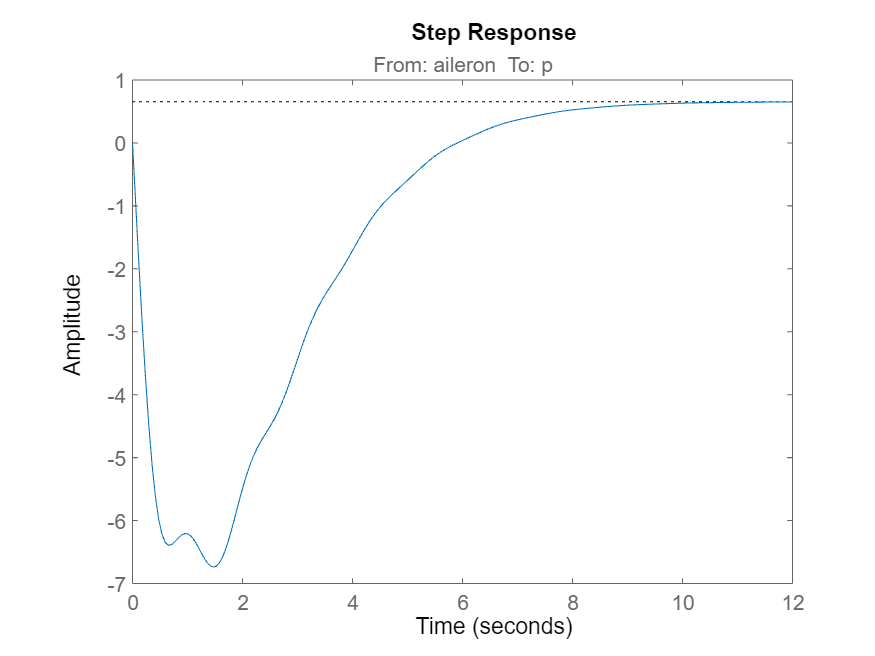

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 2.7315
    TransientTime: 7.8207
     SettlingTime: 10.5372
      SettlingMin: 0.5886
      SettlingMax: 0.6499
        Overshoot: 0
       Undershoot: 1.0317e+03
             Peak: 6.7379
         PeakTime: 1.4884


De la misma forma, se establece la función de transferencia para el yaw rate a partir de la entrada del rudder, que permitirá determinar la ganancia derivativa del controlador.


$$G_2 =\;\frac{r}{\textrm{rudder}}$$


G2 = TransferFunctions(3,2)

G2 =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



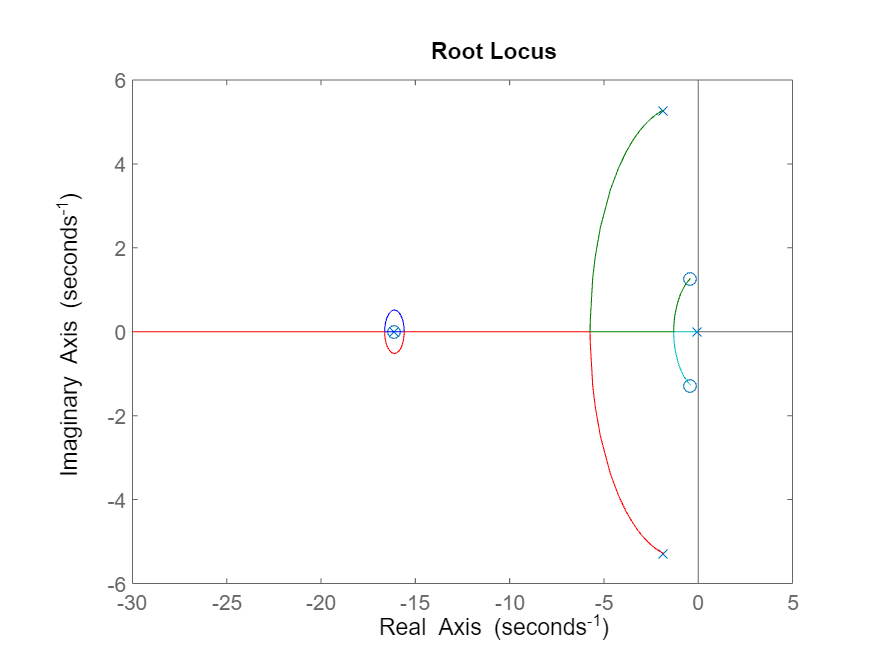

rlocus(-G2)

kd2 = -0.183;
Go2 = feedback(kd2*G2,1);
Go2.OutputName= {'r'}

Go2 =
 
  From input "rudder" to output "r":
      15.06 s^3 + 255 s^2 + 226.3 s + 432.7
  ---------------------------------------------
  s^4 + 34.85 s^3 + 345.9 s^2 + 731.4 s + 439.7
 
Continuous-time transfer function.



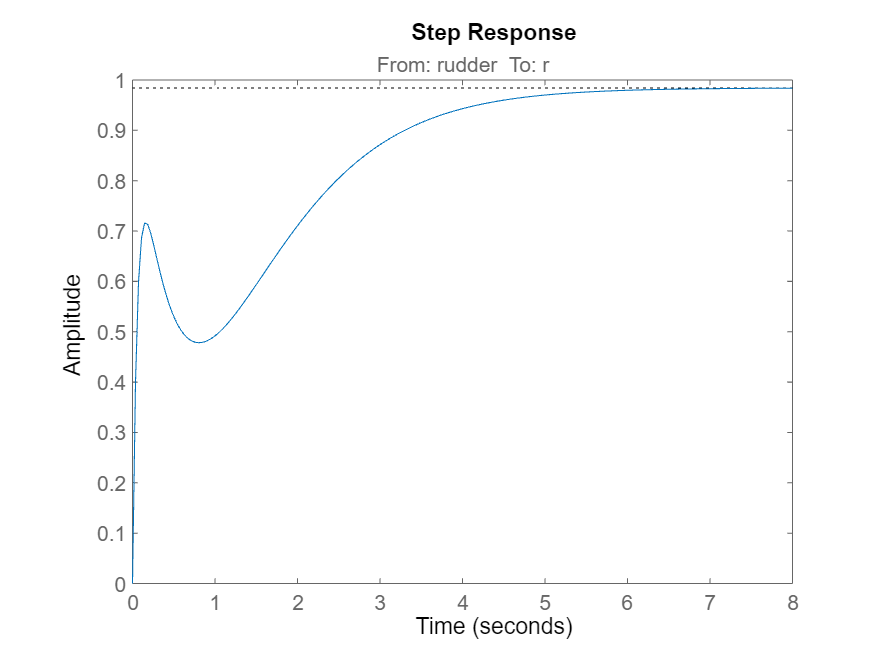

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 3.1306
    TransientTime: 4.6916
     SettlingTime: 4.6916
      SettlingMin: 0.8887
      SettlingMax: 0.9839
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9839
         PeakTime: 8.7119


#### Retroalimentación SAS

Para realizar la retroalimentación se emplean las constantes determinadas y el sistema lateral/direccional.

TransferFunctions(2,1) = kd1*TransferFunctions(2,1);
TransferFunctions(3,2) = kd2*TransferFunctions(3,2);
SASLatMod = ss(TransferFunctions)

SASLatMod =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1         0        0        0  -0.4362        0        0        0        0        0        0        0        0
   x2      0.25        0        0   -7.892        0        0        0        0        0        0        0        0
   x3         0        8        0   -11.36        0        0        0        0        0        0        0        0
   x4         0        0        8    -19.8        0        0        0        0        0        0        0        0
   x5         0        0        0        0        0        0        0  -0.4362        0        0        0        0
   x6         0        0        0        0     0.25        0        0   -7.892        0        0        0        0
   x7         0        0        0        0        0        8        0   -11.36        0        0        0        0
   x8         0        0        0        0        0        

feedin = [1 2]

feedin =      1     2


feedout = [2 3]

feedout =      2     3


CASLatMod = feedback(SASLatMod,eye(2),feedin,feedout)

CASLatMod =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1         0        0        0  -0.4362        0        0        0    28.22        0        0        0    52.33
   x2      0.25        0        0   -7.892        0        0        0    6.709        0        0        0   -81.83
   x3         0        8        0   -11.36        0        0        0    4.873        0        0        0   -43.53
   x4         0        0        8    -19.8        0        0        0        0        0        0        0   -1.251
   x5         0        0        0        0        0        0        0   -1.257        0        0        0   -15.92
   x6         0        0        0        0     0.25        0        0  -0.7668        0        0        0    135.3
   x7         0        0        0        0        0        8        0   -4.274        0        0        0    77.81
   x8         0        0        0        0        0        

#### Funciones de transferencia

Se comienza por encontrar las funciones de transferencia del sistema a partir del modelo lateral/direccional suministrado con la retroalimentación SAS.

CASTransferFunctions = tf(CASLatMod);

#### CAS Controllers

Se comienza por establecer la función de transferencia para el roll a partir de la entrada del aileron, que permitirá determinar la ganancia proporcional del controlador.


$$G_{11} =\;\frac{\textrm{phi}}{\textrm{aileron}}$$


G11 = CASTransferFunctions(4,1)

G11 =
 
  From input "aileron" to output "phi":
                                                                                                                  
  -156.3 s^10 - 8961 s^9 - 2.016e05 s^8 - 2.376e06 s^7 - 1.793e07 s^6 - 1.027e08 s^5 - 4.22e08 s^4 - 1.434e09 s^3 
                                                                                                                  
                                                                         - 3.512e09 s^2 - 6.099e09 s - 8.382e07   
                                                                                                                  
  ----------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^12 + 57.81 s^11 + 1392 s^10 + 2.205e04 s^9 + 3.139e05 s^8 + 3.441e06 s^7 + 2.153e07 s^6 + 6.341e07 s^5     
                                    

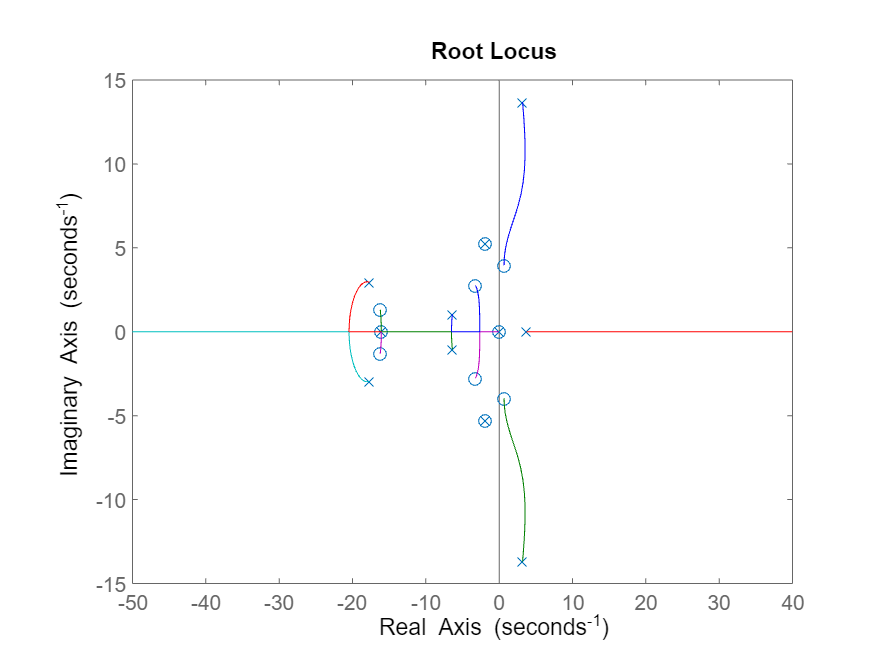

rlocus(G11)

kp1 = -0.12;
Go11 = feedback(kp1*G11,1);
Go11.OutputName= {'phi'}

Go11 =
 
  From input "aileron" to output "phi":
                                                                                                                 
  18.75 s^10 + 1075 s^9 + 2.419e04 s^8 + 2.851e05 s^7 + 2.152e06 s^6 + 1.232e07 s^5 + 5.064e07 s^4 + 1.72e08 s^3 
                                                                                                                 
                                                                         + 4.215e08 s^2 + 7.319e08 s + 1.006e07  
                                                                                                                 
  ---------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^12 + 57.81 s^11 + 1410 s^10 + 2.313e04 s^9 + 3.381e05 s^8 + 3.726e06 s^7 + 2.368e07 s^6 + 7.573e07 s^5     
                                         

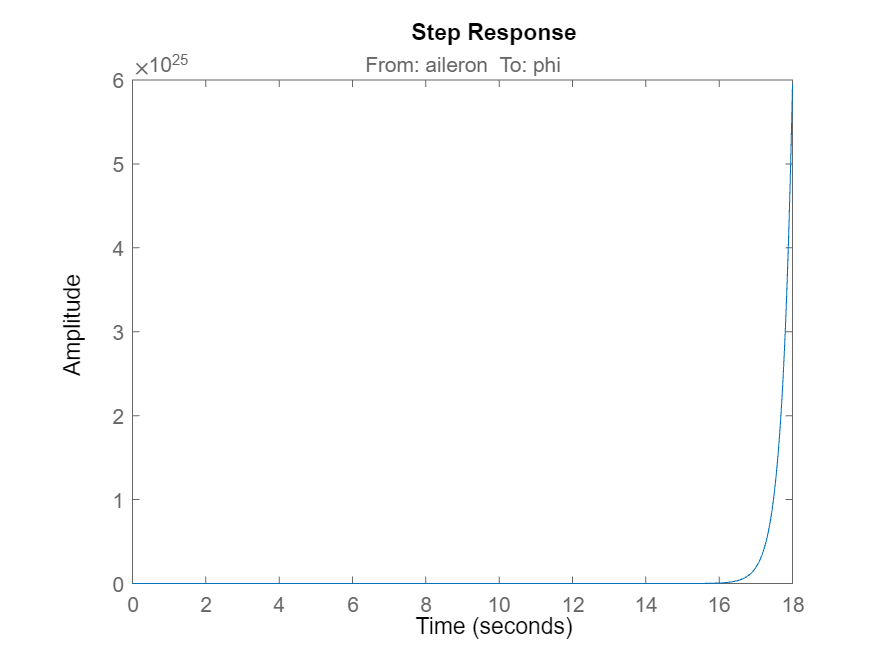

step(Go11)

stepinfo(Go11)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


De la misma forma, se establece la función de transferencia para el yaw a partir de la entrada del rudder, que permitirá determinar la ganancia proporcional del controlador.


$$G_{22} =\;\frac{\textrm{psi}\;}{\textrm{rudder}}$$


G22 = CASTransferFunctions(5,2)

G22 =
 
  From input "rudder" to output "psi":
                                                                                                               
  -82.39 s^11 - 3229 s^10 - 4.342e04 s^9 - 2.445e05 s^8 - 3.244e05 s^7 + 5.482e06 s^6 + 6.248e06 s^5           
                                                                                                               
                                           - 1.587e08 s^4 - 1.616e09 s^3 - 5.091e09 s^2 + 5.366e07 s + 1.716e06
                                                                                                               
  -------------------------------------------------------------------------------------------------------------
                                                                                                               
  s^13 + 57.81 s^12 + 1392 s^11 + 2.205e04 s^10 + 3.139e05 s^9 + 3.441e06 s^8 + 2.153e07 s^7 + 6.341e07 s^6    
                                                         

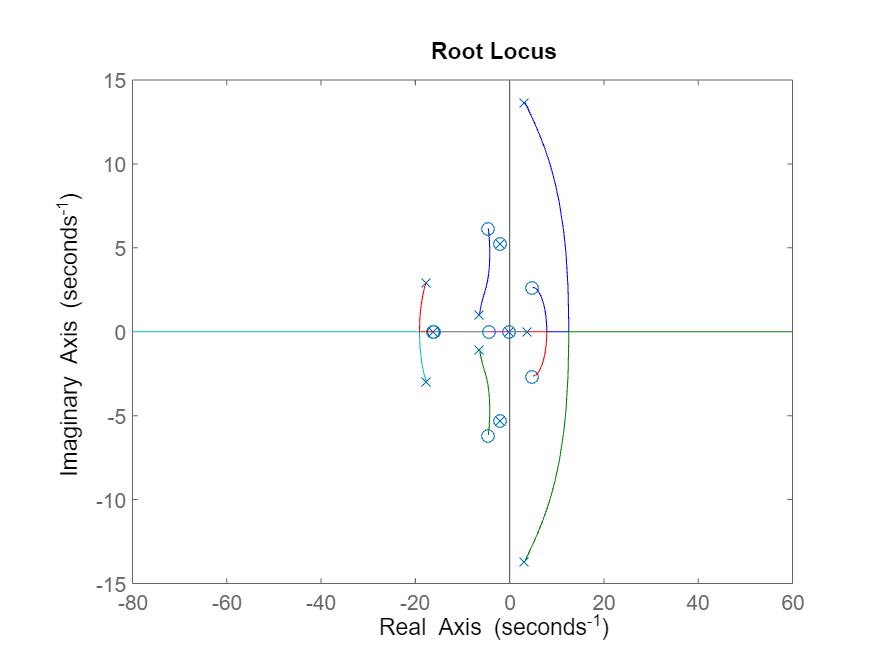

rlocus(G22)

kp2 = 0.15;
Go22 = feedback(kp2*G22,1);
Go22.OutputName= {'psi'}

Go22 =
 
  From input "rudder" to output "psi":
                                                                                                                 
  -12.36 s^11 - 484.3 s^10 - 6512 s^9 - 3.668e04 s^8 - 4.866e04 s^7 + 8.223e05 s^6 + 9.373e05 s^5 - 2.381e07 s^4 
                                                                                                                 
                                                          - 2.423e08 s^3 - 7.636e08 s^2 + 8.049e06 s + 2.574e05  
                                                                                                                 
  ---------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^13 + 57.81 s^12 + 1379 s^11 + 2.157e04 s^10 + 3.074e05 s^9 + 3.405e06 s^8 + 2.148e07 s^7 + 6.423e07 s^6    
                                          

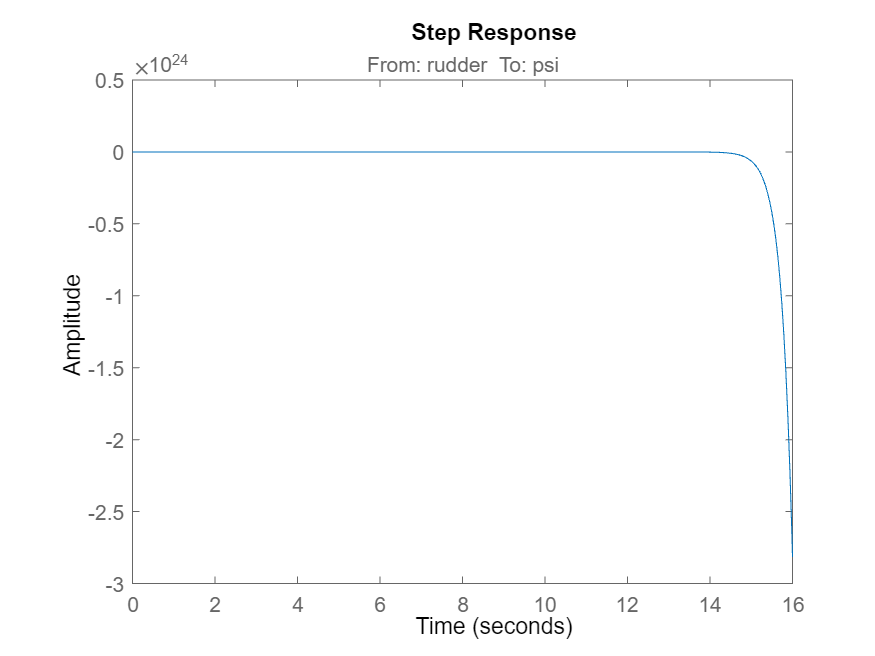

step(Go22)

stepinfo(Go22)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


Como se observa las respuestas no son las esperadas y se debe a la inestabilidad que se produce al realizar la realimentación SAS y todos los problemas que ya se mencionaron en el informe presentado.

## Controlador H inf

clear
close all
load("modelo_lin.mat");

En el taller que se entregó, a pesar de que se realizó la implementación de un diseño Hinf, se reconoce ciertos elementos faltantes o para mejorar en el desarrollo del mismo.

### Filtros

Para empezar, los diseños de los filtros W1, W2 y W3 para el sistema longitudinal y el lateral/direccional se realizaron con un valor de ganancia media sin justificar, ya que solo se realizó un proceso iterativo. Dicho esto, ahora se van a diseñar los filtros teniendo en cuenta las frecuencias de corte del filtro, es decir, cuando la ganancia es 3dB menor a la ganancia máxima, es decir, cuando la potencia de la señal de salida se ha reducido a aproximadamente el 50% y se considera que empieza a ocurrir efectivamente el filtrado.

####  Sistema Lateral/Direccional

W1_LD = makeweight(db2mag(23),[1 db2mag(20)],db2mag(-15)); %filtro pasa bajos
W2_LD = makeweight(db2mag(-28),[8500 db2mag(-8.2)],db2mag(-5.2)); %filtro pasa altos
W3_LD = makeweight(db2mag(-20),[500 db2mag(17)],db2mag(20)); %filtro pasa altos

Con estos nuevos filtros, se diseña una frecuencia de corte de 1 rad/s para el filtro pasa bajos W1, de 8500 rad/s para el filtro pasa altos W2, y de 500 rad/s para el filtro pasa altos W3.

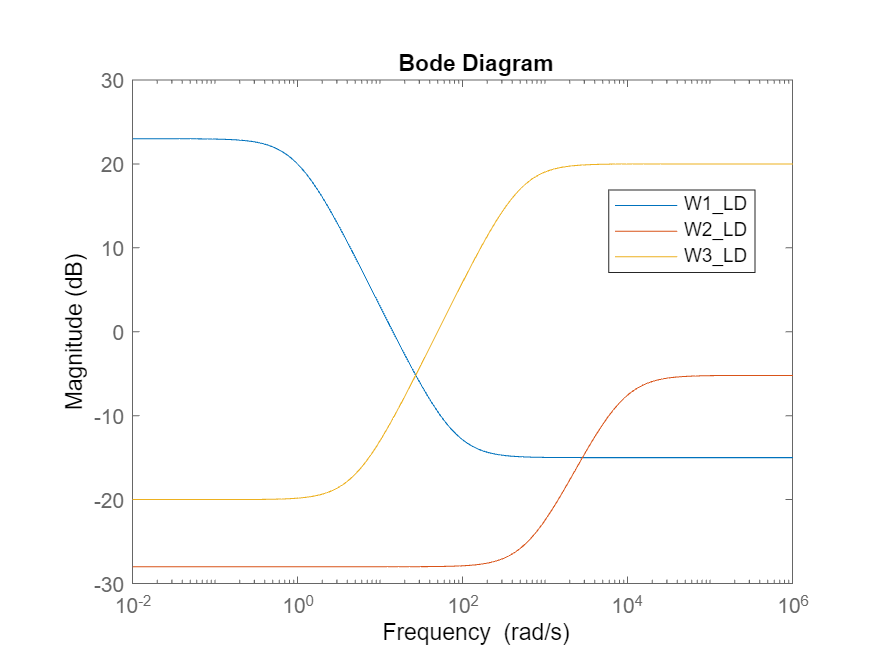

bodemag(W1_LD,W2_LD,W3_LD)
legend("Location","best")

#### Sistema Longitudinal

Para los filtros del sistema longitudinal se seleccionan frecuencias de corte de 0.07 rad/s para el filtro pasa bajos W1, de 36 rad/s para el filtro pasa altos W2, y de 2600 rad/s para el filtro pasa altos W3.

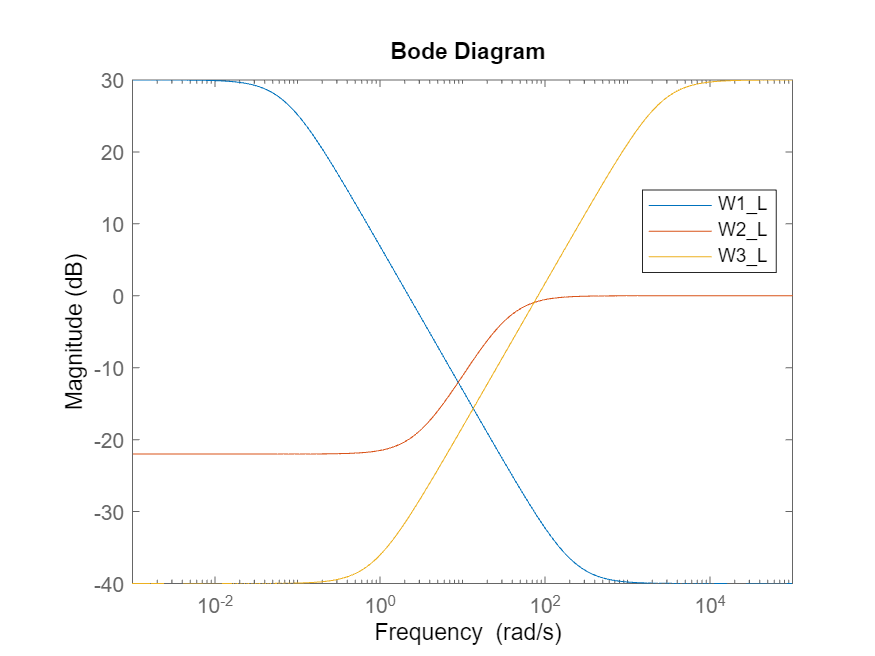

W1_L = makeweight(db2mag(30),[0.07 db2mag(27)],db2mag(-40)); %filtro pasa bajos
W2_L = makeweight(db2mag(-22),[36 db2mag(-3)],db2mag(0)); 
W3_L = makeweight(db2mag(-40),[2600 db2mag(27)],db2mag(30)); %filtro pasa altos
bodemag(W1_L,W2_L,W3_L)
legend("Location","best")

### Controladores Hinf

Ya con estos filtros redefinidos teniendo en cuenta adecuadamente las frecuencias de corte, se realiza la definición de los dos controladores a implementar. Esto se realiza al igual que en la entrega inicial.

#### Sistema Lateral/Direccional

Wp=makeweight(1,[10 0.1],0.01);
W1Phi= W1_LD;W1Psi= W1_LD;
W2Aileron= W2_LD;W2Rudder= W2_LD;
W3Phi=W3_LD;W3Psi=W3_LD;
Wn= 0.001;
systemnames= 'latmod Wp Wn W1Phi W1Psi W2Aileron W2Rudder W3Phi W3Psi';
inputvar= '[per; n; rPhi; rPsi; uAileron; uRudder]';
outputvar= '[W1Phi; W1Psi; W2Aileron; W2Rudder; W3Phi; W3Psi; -latmod(4) - Wn + rPhi;-latmod(5) - Wn + rPsi]';
input_to_latmod= '[-Wp + uAileron; -Wp + uRudder]';
input_to_Wn= '[n]';input_to_Wp     = '[per]';
input_to_W1Phi= '[-latmod(4) - Wn + rPhi]';input_to_W1Psi= '[-latmod(5) - Wn + rPsi]';
input_to_W2Phi= '[uAileron]';input_to_W2Psi= '[uRudder]';
input_to_W3Phi= '[latmod(4)]';input_to_W3Psi= '[latmod(5)]';
Planta = sysic;

ncont = 2; nmeas = 2; 
[K_LatDir,CL_LD,gamma_LD] = hinfsyn(Planta,nmeas,ncont);

A partir de este replanteamiento de controlador Hinf, se obtiene un gamma de $\gamma_{\textrm{LD}} =0\ldotp 7973$

%Función de Lazo abierto
L_LD = latmod*K_LatDir;
%Sistema en Lazo cerrado
Go_LD = feedback(L_LD,eye(2),[1,2],[4,5]);Go_LD.InputName={'aileron','rudder'};

Calculando el ancho de banda tanto para el control lateral y direccional, se determina que son de:

BWPhi = bandwidth(Go_LD(4,1))/2/pi

BWPhi = 5.7307

BWPsi = bandwidth(Go_LD(5,2))/2/pi

BWPsi = 4.8510

Unidades de rad/s.

#### Sistema Longitudinal

[K_Long,CL_L,gamma_L] = mixsyn(G_LongMod(1,1),W1_L,W2_L,W3_L);

A partir de este replanteamiento de controlador Hinf, se obtiene un gamma de $\gamma_L =0\ldotp 3919$

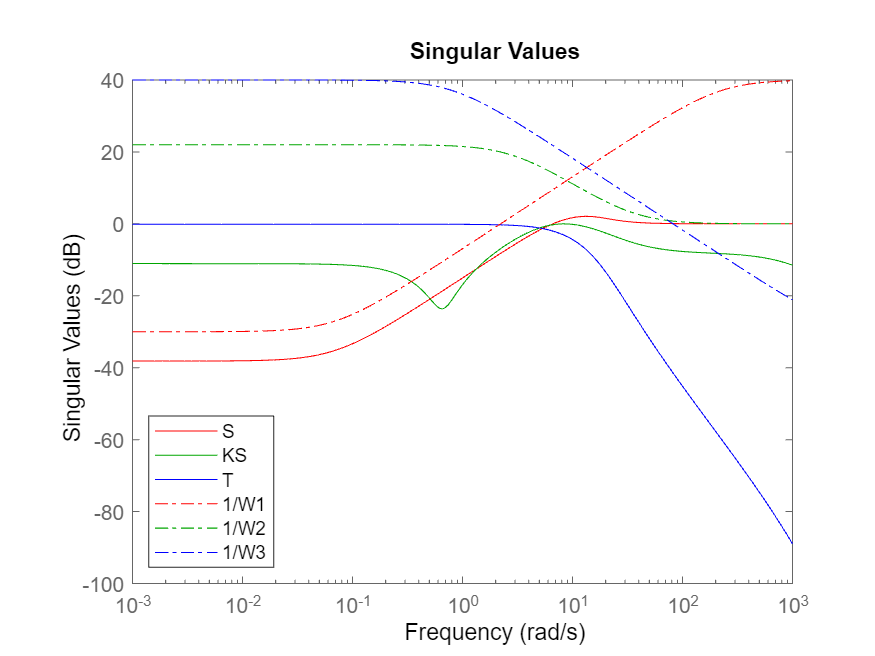

S_L = feedback(1,G_LongMod(1,1)*K_Long);
KS_L = K_Long*S_L;T_L = 1-S_L;
sigma(S_L,'r',KS_L,'g',T_L,'b',1/W1_L,'r-.',ss(1/W2_L),'g-.',1/W3_L,'b-.',{1e-3,1e3})
legend('S','KS','T','1/W1','1/W2','1/W3','Location','SouthWest')

OL_L=series(K_Long,G_LongMod(1,1));
GCL=feedback(OL_L,1);

GCL.InputName="elevator";

Calculando el ancho de banda  para el control longitudinal, se determina que es de:

bandwidth(GCL)/(2*pi)

ans = 1.3266

Unidades de rad/s.

### Análisis de velocidad

Ahora bien, algo que no se mencionó en la primera entrega, fue hacer análisis de la velocidad de los sistemas, ya que se debía mostrar que esta convergía a 0 para poder generar un set-point tracking adecuado.

#### Sistema ideal

**    Lateral/Direccional **

Para estos sistemas ideales que no contemplan ruido, incertidumbres ni perturbaciones, se realizan las gráficas del efecto paso en el alerón a la velocidad *p*, y del rudder a la velocidad *r *para el sistema Lateral/Direccional

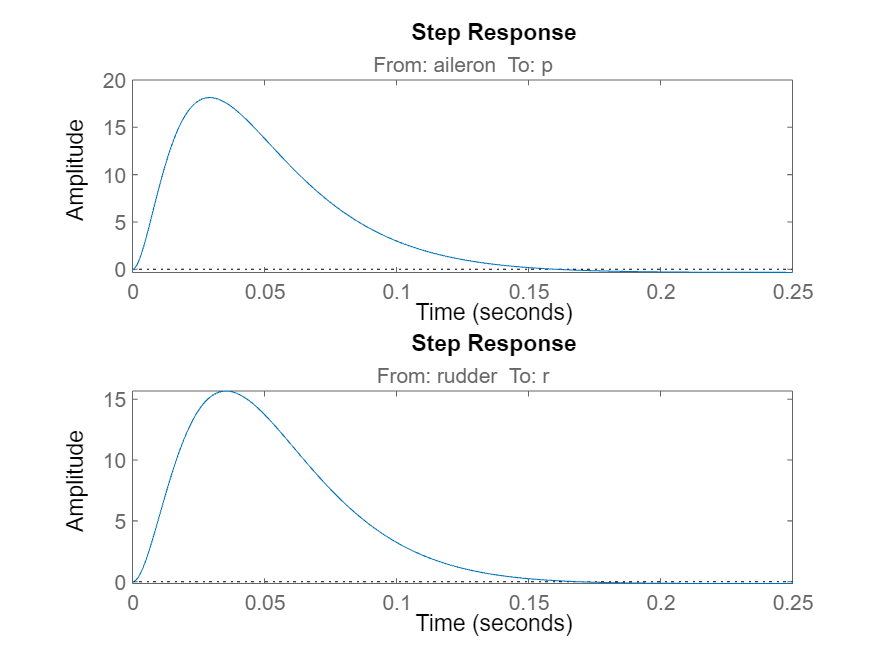


figure()
subplot(2,1,1)
step(Go_LD(2,1));
subplot(2,1,2)
step(Go_LD(3,2));

Como se puede ver en estas dos figuras, la velocidad de estos dos sistemas converge a un valor de cero, o cercano a este. En el caso de la velocidad *p, * esta no converge a 0 debido al acoplamiento que hay entre los sistemas lateral y direccional, sin embargo se evidencia que este valor no es significativo y que viene como propiedad intrínseca del sistema.

Dicho esto, se asume que en tiempos $>5\tau$ se logra converger a un estado estable de posición con el objetivo de cumplir con el set point tracking para este sistema.

**    Sistema Longitudinal **

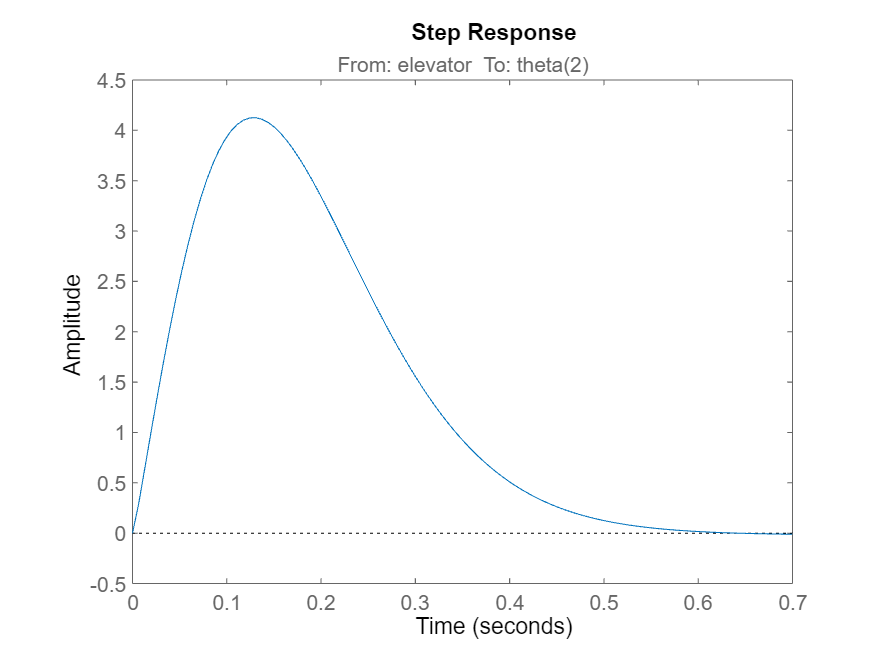

figure()
step(series(series(GCL,G_LongMod(1,1)^(-1)),G_LongMod(2,1)));

Como se puede ver en estas dos figuras, la velocidad de este sistema converge a un valor de cero, lo cual implica que en tiempos $>5\tau$ se logra converger a un estado al igual que en sistema anterior, lo que permite realizar el set-point tracking adecuadamente.

#### Sistema lineal con perturbaciones, incertidumbres y ruido

Para finalizar, se vuelven a hacer estas pruebas de velocidad pero para el sistema general en simulink de la planta completa. Se implementan los mismos set points que se realizaron en la entrega anterior.

Vals_Sim=sim("T1HinfFinal.slx");

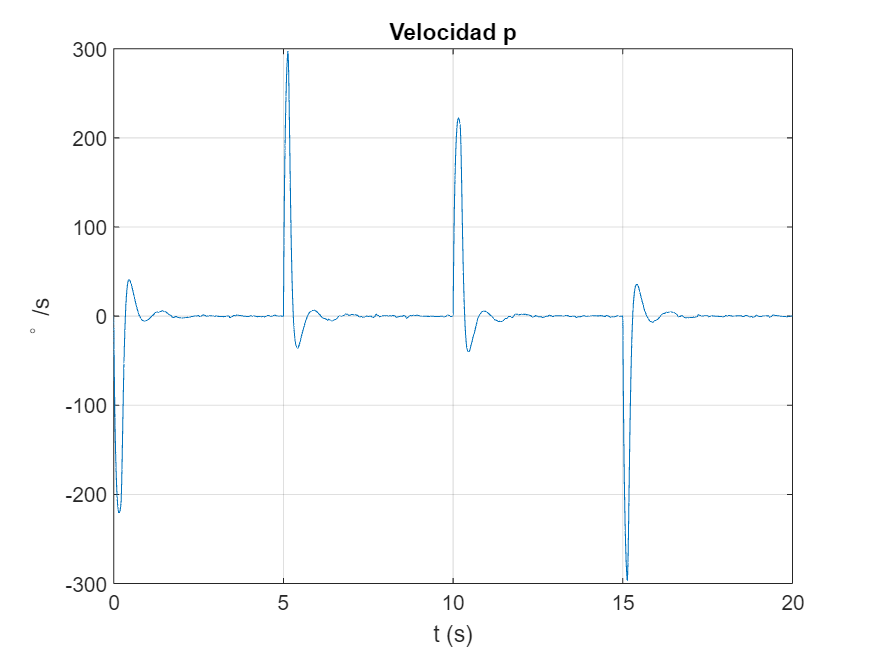

plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,2))
title("Velocidad p")
xlabel("t (s)");ylabel("^\circ /s");grid

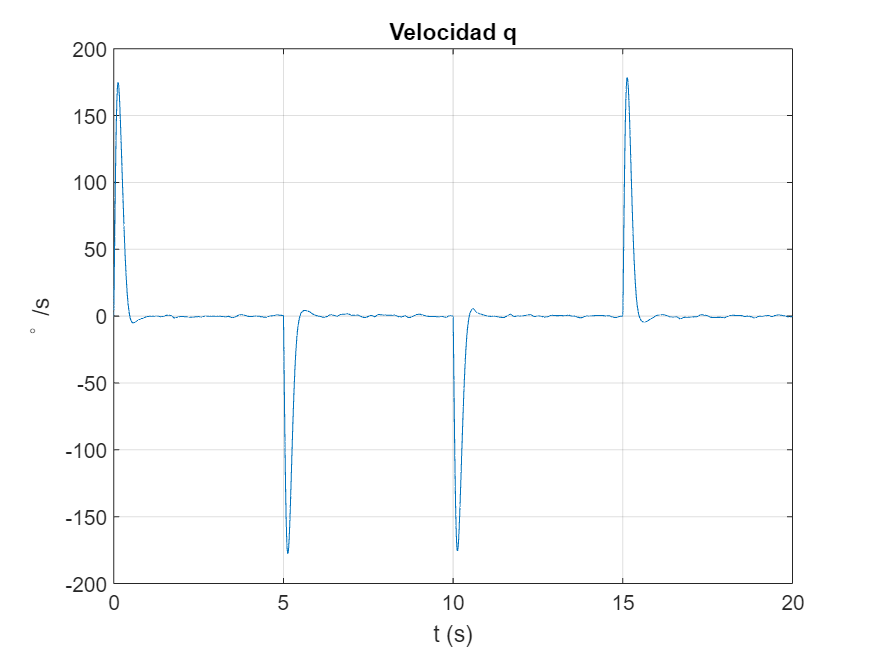


plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,1))
title("Velocidad q")
xlabel("t (s)");ylabel("^\circ /s");grid

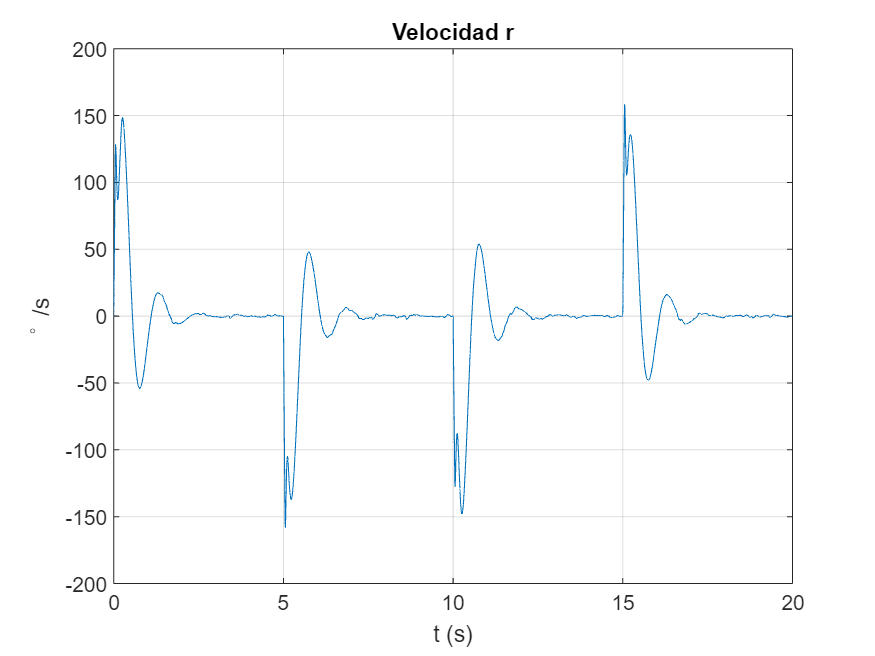


plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,3))
title("Velocidad r")
xlabel("t (s)");ylabel("^\circ /s");grid

Como se puede evidenciar, estos valores tienen picos en los saltos de referencia de posición, y luego se reducen hasta oscilar cercano a velocidad nula. Para analizar un poco mejor estos valores, se realiza una selección del intervalo de tiempo entre los 18s y 20s para analizar esta velocidad.

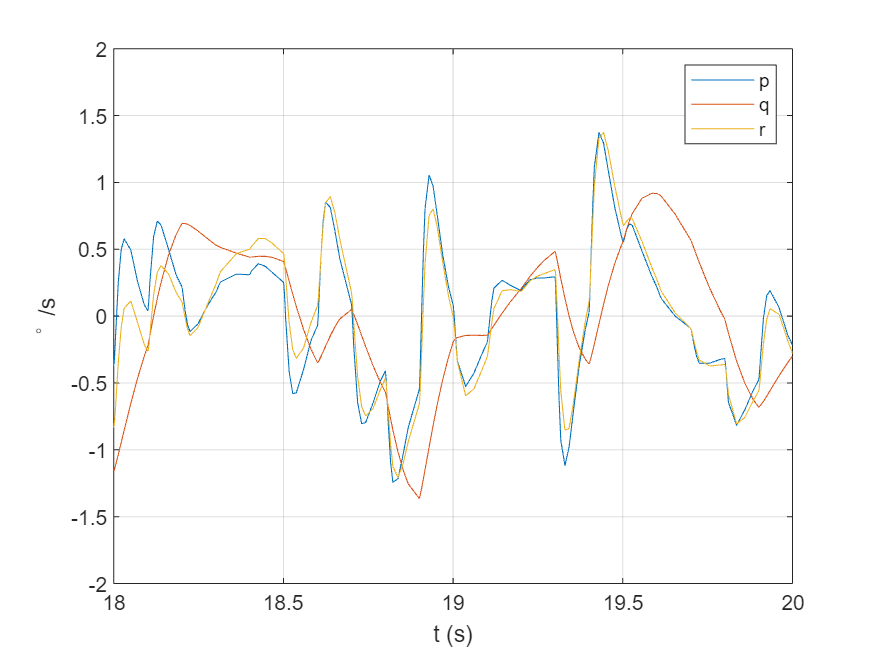

plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,2))
hold on
plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,1))
plot(Vals_Sim.vel.Time,Vals_Sim.vel.Data(:,3))
hold off
xlabel("t (s)");ylabel("^\circ /s")
legend("p","q","r");axis([18 20 -2 2]);grid

Como se puede evidenciar, los efectos externos están generando osculaciones de velocidad acotadas entre $V\in \left\lbrack -1\ldotp 5^{\circ } \;1\ldotp 5^{\circ } \right\rbrack s^{-1}$, lo cual es entendible debido a las condiciones del sistema.

Con todo y lo anterior, se establece que la velocidad efectivamente logra converger a valores cercanos y oscilantes a 0, los cuales son producidos por la correción de velocidad para lograr mitigar los efectos de factores externos del sistema.